%=================================
%Group 5  IITB 2021
% This code is of Modified Algorithm
%=================================
clear ;
close all;
clc

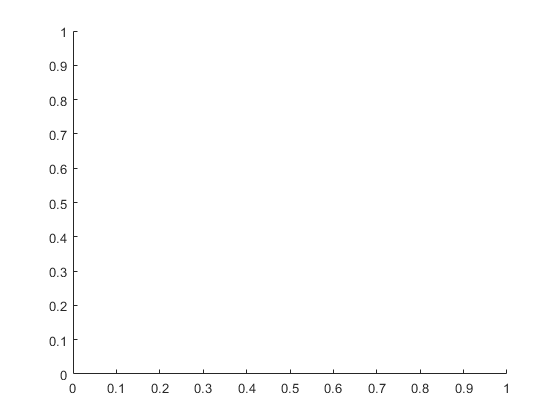

%clear all
%close all
%clc

im=imread('chestXray.png');
wname='haar';

msg=' work is worship ';
%text = fread(msg, inf, 'uint8');
%bin_text = de2bi(text, 8);
data=[];
for(i=1:length(text))
d=msg(i)+0;
data=[data d];
end

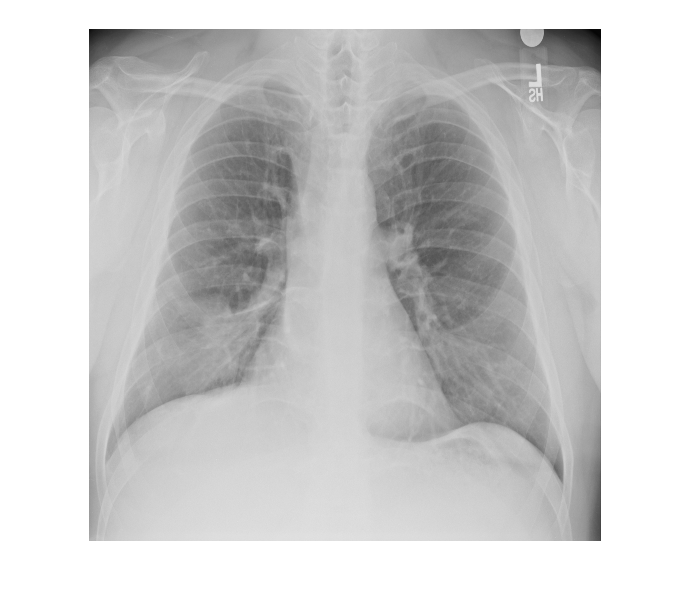



[cA1,cH1,cV1,cD1] = dwt2(im,wname);
dec1 = [cA1 cH1; 
cV1 cD1 
];


M=max(data);
data_norm=data/M;
n=length(data);
[x y]=size(cH1);
cH1(1,1)=-1*n/10;
cH1(1,2)=-1*M/10;

for(i=1:1:ceil(n/2))
cV1(i,y)=data_norm(i);
end

for(i=ceil(n/2)+1:1:n)
cD1(i,y)=data_norm(i);
end

CODED1=idwt2(cA1,cH1,cV1,cD1,wname);

figure

[x y]=size(cA1);

imshow(uint8(CODED1))


ms=abs(CODED1-double(im));
ms=ms.*ms;
ms=mean(mean(ms))

ms = 7.8201e-06

ps= (255*255)/ms;
ps=10*log10(ps)

ps = 99.1987

imwrite(uint8(CODED1),'Stego.png','png'); 
return

## Cover Image & Secret Image

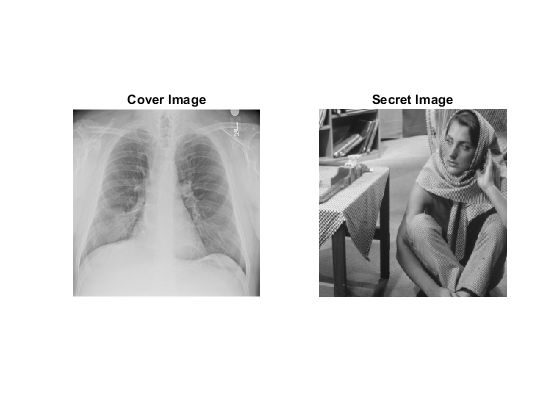

CoverImage=imread('stego.png');
SecretImage=imread('barbara.png');

%CoverImage=rgb2gray(CoverImage);
%SecretImage=rgb2gray(SecretImage);

CoverImage=imresize(CoverImage,0.5);
SecretImage=imresize(SecretImage,0.5);

figure(1);
subplot(1,2,1);
imshow(CoverImage);
title('Cover Image');

subplot(1,2,2);
imshow(SecretImage);
title('Secret Image');

## DWT of Cover Image

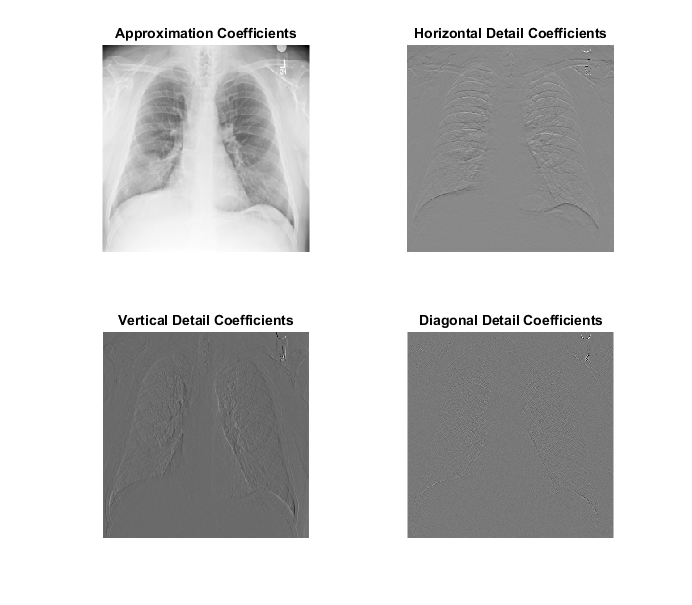

[ICA,ICH,ICV,ICD] = dwt2(CoverImage, 'haar');

figure(2);
subplot(2,2,1);
imshow(mat2gray(ICA));
title('Approximation Coefficients');

subplot(2,2,2);
imshow(mat2gray(ICH));
title('Horizontal Detail Coefficients');

subplot(2,2,3);
imshow(mat2gray(ICV));
title('Vertical Detail Coefficients');

subplot(2,2,4);
imshow(mat2gray(ICD));
title('Diagonal Detail Coefficients');

## DWT of Secret Image

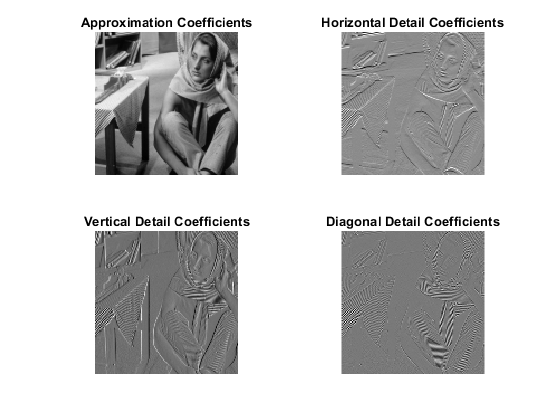

[SCA,SCH,SCV,SCD] = dwt2(SecretImage, 'haar');

figure(3);
subplot(2,2,1);
imshow(mat2gray(SCA));
title('Approximation Coefficients');

subplot(2,2,2);
imshow(mat2gray(SCH));
title('Horizontal Detail Coefficients');

subplot(2,2,3);
imshow(mat2gray(SCV));
title('Vertical Detail Coefficients');

subplot(2,2,4);
imshow(mat2gray(SCD));
title('Diagonal Detail Coefficients');

## Embedding

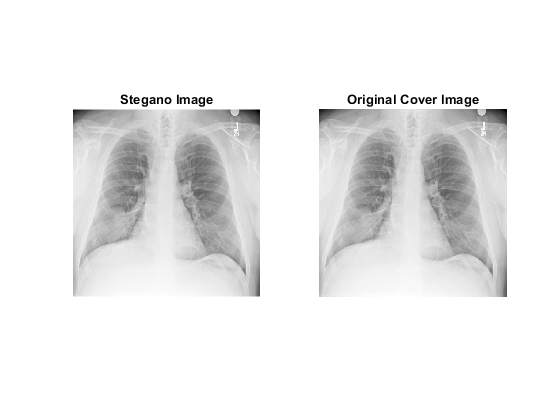

m=4;
BS = mat2cell(SCA,repmat(m,1,size(SCA,1)/m),repmat(m,1,size(SCA,2)/m));
BC = mat2cell(ICA,repmat(m,1,size(ICA,1)/m),repmat(m,1,size(ICA,2)/m));
BD = mat2cell(ICD,repmat(m,1,size(ICD,1)/m),repmat(m,1,size(ICD,2)/m));

BS = reshape(BS,1,size(BS,1)*size(BS,2));
BC = reshape(BC,1,size(BC,1)*size(BC,2));
BD = reshape(BD,1,size(BD,1)*size(BD,2));

EB=BS;

K1 = zeros(1,size(BS,2));
K2 = zeros(1,size(BS,2));
K3=100;
MSE1 = zeros(size(BS,2),size(BC,2));
MSE2 = zeros(size(BS,2),size(BC,2));
for i=1:size(BS,2)
    for j=1:size(BC,2)
        if any(ismember(K1,j))
            MSE1(i,j)=999999;
        else
            MSE1(i,j) = immse(BS{i},BC{j});
        end
    end
    [~,K1(i)]=min(MSE1(i,:));
    EB{i}=(BC{K1(i)}-BS{i})/K3;
end

for i=1:size(EB,2)
    for k=1:size(BD,2)
        if any(ismember(K2,k))
            MSE2(i,k) = 999999;
        else
            MSE2(i,k) = immse(EB{i},BD{k});
        end
    end
    [~,K2(i)]=min(MSE2(i,:));
    BD{K2(i)}=EB{i};
end

BS = reshape(BS,size(SCA,1)/m,size(SCA,2)/m);
BC = reshape(BC,size(ICA,1)/m,size(ICA,2)/m);
BD = reshape(BD,size(ICD,1)/m,size(ICD,2)/m);

mICA=ICA;
mICH=ICH;
mICV=ICV;
mICD=cell2mat(BD);

SteganoImage=idwt2(mICA,mICH,mICV,mICD,'haar');

figure(4);
subplot(1,2,1);
imshow(mat2gray(SteganoImage));
title('Stegano Image');

subplot(1,2,2);
imshow(mat2gray(idwt2(ICA,ICH,ICV,ICD,'haar')))
title('Original Cover Image');

## Extraction

[GCA,GCH,GCV,GCD] = dwt2(SteganoImage, 'haar');
figure(1);
%subplot(1,2,1);
imwrite(CoverImage,'cbi.png') 
imshow(CoverImage);
title('Cover Image');

%subplot(1,2,2);
imshow(SecretImage);
title('Secret Image');

## DWT of Cover Image

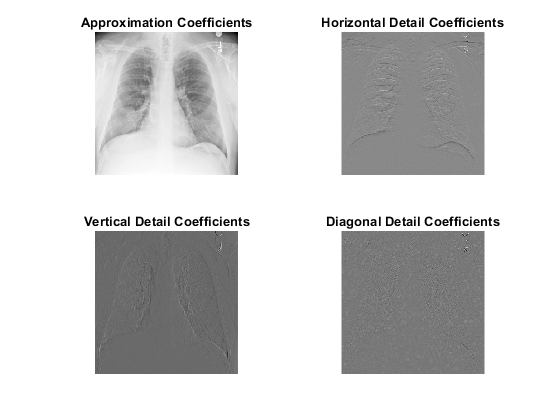

[ICA,ICH,ICV,ICD] = dwt2(CoverImage, 'haar');

figure(5);
subplot(2,2,1);
imshow(mat2gray(GCA));
title('Approximation Coefficients');

subplot(2,2,2);
imshow(mat2gray(GCH));
title('Horizontal Detail Coefficients');

subplot(2,2,3);
imshow(mat2gray(GCV));
title('Vertical Detail Coefficients');

subplot(2,2,4);
imshow(mat2gray(GCD));
title('Diagonal Detail Coefficients');

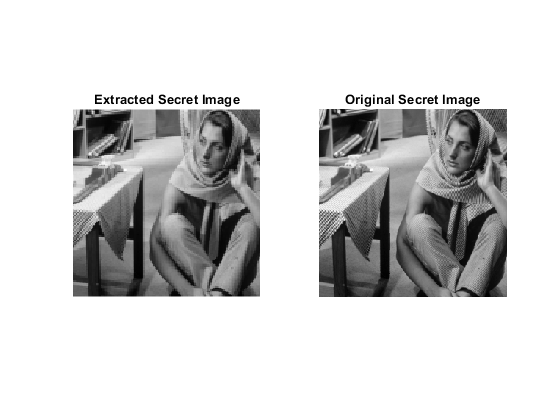


eBD = mat2cell(GCD,repmat(m,1,size(GCH,1)/m),repmat(m,1,size(GCH,2)/m));
eBC = mat2cell(GCA,repmat(m,1,size(GCA,1)/m),repmat(m,1,size(GCA,2)/m));
eBS = cell(1,size(K1,2));

eBC = reshape(eBC,1,size(eBC,1)*size(eBC,2));
eBD = reshape(eBD,1,size(eBD,1)*size(eBD,2));

for i=1:size(K1,2)
    eBS{i}=eBC{K1(i)}-K3*eBD{K2(i)};
end

eBS = reshape(eBS,size(SCA,1)/m,size(SCA,2)/m);

eSCA=cell2mat(eBS);
eSCH=zeros(size(eSCA));
eSCV=zeros(size(eSCA));
eSCD=zeros(size(eSCA));

eSecretImage=idwt2(eSCA,eSCH,eSCV,eSCD,'haar');

figure(6);
subplot(1,2,1);
imshow(mat2gray(eSecretImage));
title('Extracted Secret Image');

subplot(1,2,2);
imshow(mat2gray(idwt2(SCA,SCH,SCV,SCD,'haar')))
title('Original Secret Image');

## Metric

ErrorSecret=immse(mat2gray(eSecretImage),mat2gray(SecretImage));
ErrorStegano=immse(mat2gray(SteganoImage),mat2gray(CoverImage));

## **Extraction Of Text from Cover_image**

im=imread('cbi.png');
[cA11,cH11,cV11,cD11] =dwt2(CODED1,'haar');
data=[]


data =

     []



data_norm=[];
n=ceil(abs(cH11(1,1)*10));
M=ceil(abs(cH11(1,2)*10));

for(i=1:1:ceil(n/2))
data_norm(i)=cV11(i,y);
end

for(i=ceil(n/2)+1:1:n)
data_norm(i)=cD11(i,y);
end
data=ceil(data_norm*M)-1;
msg1='';
for(i=1:length(data))
msg1=strcat(msg,data(i));
end

msg1

msg1 = ' work is worship'